## **Connect to the NVIDIA Hardware**

젯슨 보드 연결

hwobj = jetson('192.168.0.37','jetson','jet0000');

Checking for CUDA availability on the Target...
Checking for 'nvcc' in the target system path...
Checking for cuDNN library availability on the Target...
Checking for TensorRT library availability on the Target...
Checking for prerequisite libraries is complete.
Gathering hardware details...
Gathering hardware details is complete.
 Board name        : NVIDIA Jetson TX1
 CUDA Version      : 10.0
 cuDNN Version     : 7.6
 TensorRT Version  : 6.0
 Available Webcams : C922 Pro Stream Webcam
 Available GPUs    : NVIDIA Tegra X1


## 웹캠 바로 설정

cam = webcam(hwobj);

## 웹캠 테스트 5초

웹캠이 잘 동작하는지만 확인

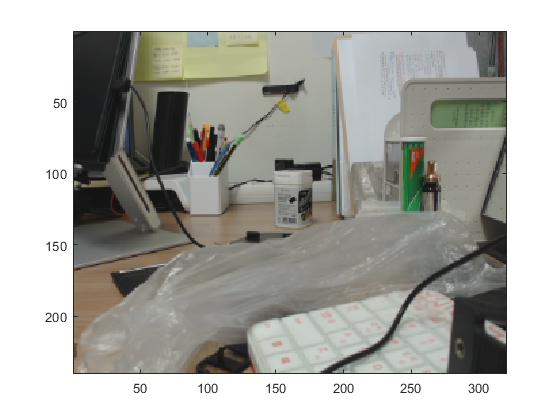

tic;
while toc < 5
    img = snapshot(cam);
    image(img);
    drawnow
end

## 웹캠 GOOGLENet 적용

되는지만 확인용, 연산은 모두 MATLAB에서

파일입출력 테스트

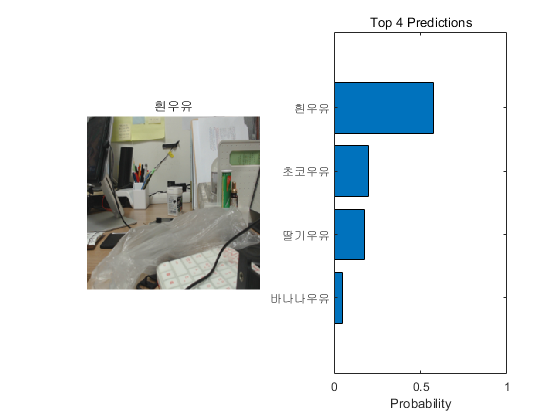

load("googlenetTransfer.mat","googlenetTransfer")
 
tic;
while toc < 10
    img = snapshot(cam);
    img = imresize(img, [224 224]);
    [label, scores] = classify(googlenetTransfer,img);
    
    [~, idx] = sort(scores,'descend');
    idx = idx(4:-1:1);
    classNamesTop = googlenetTransfer.Layers(end).Classes(idx);
    scoresTop = scores(idx);
    
    figure(1),
    subplot(121), imshow(img)
    title(label);
    subplot(122), barh(scoresTop)
    xlim([0 1]);
    title('Top 4 Predictions')
    xlabel('Probability')
    yticklabels(classNamesTop)    
    drawnow;
end

# **CUDA 코드**

GPU coder에 변환할 m파일 함수를 먼저 만들고 실행.

## **Generate CUDA Code for the Target Using GPU Coder**

Coder 설정 변수들. GPU Coder를 사용하면 그냥 알아서 되는거 같기도...

cfg = coder.gpuConfig('exe');
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.Hardware.BuildDir = '~/remoteBuildDir';
cfg.GenerateExampleMain = 'GenerateCodeAndCompile';
cfg.BuildConfiguration = 'Faster Builds';
disp('타켓 확인')

타켓 확인


## generate CUDA code

딥러닝이 포함되어 있어서 그런지 오래걸림...

tic;
codegen('-config', cfg, 'MyNetJetson', '-report')


Warning in ==> MyNetJetson Line: 38 Column: 1
Code generation successful (with warnings): View report


t = toc/60;
disp([num2str(t),'분 경과'])

2.3974분 경과


#### 파이썬 코드를 젯슨보드에 전송

hwobj.putFile('gpio_test.py', hwobj.workspaceDir);

## **Run the Sobel Edge Detection on the Target**

**프로그램 실행**

exe = [hwobj.workspaceDir '/MyNetJetson.elf'];
pid = hwobj.runExecutable(exe);

### Launching the executable on the target...
Executable launched successfully with process ID 13608.
Displaying the simple runtime log for the executable...

Note: For the complete log, run the following command in the MATLAB command window:
system(hwobj,'cat /home/jetson/remoteBuildDir/MATLAB_ws/R2019b/C/Users/SSPLab1/Documents/MATLAB/MyNetJetson.log');


### 프로그램 종료

프로세스 번호를 킬

killApplication(hwobj,exe)
%killProcess(hwobj,pid)